# 4.9 Discrete controller and observer

% select the sampling time
fSamplingPeriod = 0.005;

load poles.mat
load Linear_Param.mat
poles

poles =  -475.0652
   -6.7148
   -4.8186
   -0.0000


A;
B = B(:,1);
C = [1 0 0 0;
    0 0 1 0];
D = 0;
contStateSpace = ss(A,B,C,D)

contStateSpace =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0    -435  -6.099   9.136
   x3       0       0       0       1
   x4       0    1903   62.02  -39.97
 
  B = 
           u1
   x1       0
   x2   20.58
   x3       0
   x4  -90.03
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



discreteStateSpace = c2d(contStateSpace,fSamplingPeriod);
Ad = discreteStateSpace.A

Ad =     1.0000    0.0022   -0.0000    0.0001
         0    0.1693   -0.0095    0.0174
         0    0.0124    1.0006    0.0047
         0    3.6357    0.2185    0.9242


Bd = discreteStateSpace.B

Bd =     0.0001
    0.0393
   -0.0006
   -0.1720


Cd = discreteStateSpace.C

Cd =      1     0     0     0
     0     0     1     0


D = discreteStateSpace.D

D =      0
     0


discretePoles = exp(poles*fSamplingPeriod)

discretePoles =     0.0930
    0.9670
    0.9762
    1.0000



%Plotting discrete poles
scatter(real(discretePoles),imag(discretePoles))
hold on
r = 1

r = 1

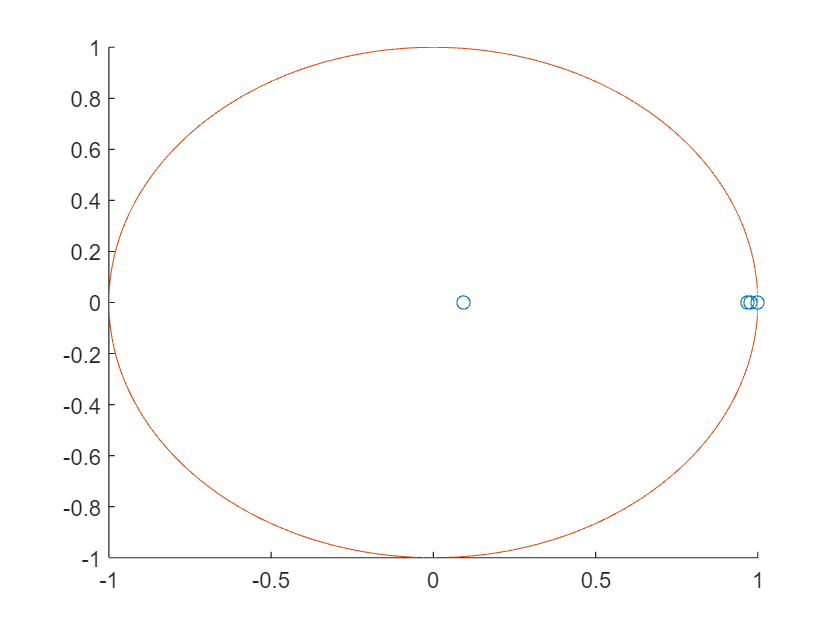

ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(xp,yp);
hold off

Controller

%State-feedback gain
Kd = place(Ad,Bd,discretePoles)

Kd =    -0.0000  -41.6818  -61.0018   -9.6533


eig(Ad-Bd*Kd)

ans =     1.0000
    0.0930
    0.9670
    0.9762


Full-state observer

factor = 4;
speed = max(abs(poles(2:4)));
contObserverPoles(1) = poles(1);
contObserverPoles(2) = -6*factor*speed; % Place pole to not disturb dominant poles

omegan = factor*speed;
zeta = 0.8;
contObserverPoles(3:4) =    [omegan*(-zeta+1i*sqrt(1-zeta^2));
                omegan*(-zeta-1i*sqrt(1-zeta^2))];
desiredPoles = exp(contObserverPoles*factor*fSamplingPeriod)

desiredPoles =    0.0001 + 0.0000i   0.0398 + 0.0000i   0.6172 + 0.2061i   0.6172 - 0.2061i


Ld = (place(Ad',Cd',desiredPoles))'

Ld =     1.0319    0.0657
   -0.8933    2.8158
   -0.8426    0.7880
 -123.0034   22.8853


eig(Ad-Ld*Cd)

ans =    0.6172 + 0.2061i
   0.6172 - 0.2061i
   0.0001 + 0.0000i
   0.0398 + 0.0000i


Reduced order observer

T = [C;0 1 0 0; 0 0 0 1];
An = inv(T)*Ad*T ;  %New A-matrix
Bn = inv(T)*Bd;     %New B-matrix
Cbacc = Cd(1,:)*T;  %Accurate
Cbnacc = Cd(2,:)*T; %Not accurate

Ayy = An(1,1); %Zero
Ayx = An(1,2:4);  %Noisy/unobserved states
Axy = An(2:4,1); % Zero
Axx = An(2:4,2:4); %Noisy/unobserved states

By = Bn(1);
Bx = Bn(2:4);

Cy = Cbnacc(1);
Cx = Cbnacc(2:4);

AA = Axx;
CC = [Ayx
      Cx];
Lpartial = ( place( AA', CC', desiredPoles(2:4) ) )';
Lacc = Lpartial(:,1);
Lnacc = Lpartial(:,2);

poles(2:4);
observerPoles = eig(AA-Lpartial*CC)

observerPoles =    0.0398 + 0.0000i
   0.6172 + 0.2061i
   0.6172 - 0.2061i



M1d = Axx-Lacc*Ayx-Lnacc*Cx

M1d =     0.0455    0.0453    0.0056
    0.0536    0.4692    0.0256
   -0.2944   -2.3840    0.7595


M2d = Bx-Lacc*By

M2d =     0.0014
    0.0578
   -0.5435


M3d = Axy-Lacc*Ayy-Lnacc*Cy

M3d = 1.0e+03 *

    0.0152
    0.1382
   -2.7748


M4d = Lnacc

M4d =     0.9546
   -0.0680
    0.6117


M5d = Lacc

M5d = 1.0e+03 *

   -0.0152
   -0.1382
    2.7748


M6d = T(:,1)

M6d =      1
     0
     0
     0


M7d = T(:,2:4)

M7d =      0     0     0
     0     1     0
     1     0     0
     0     0     1
